% 参数设置
% 本代码是用来模拟手动找峰看最后的结果对不对，CIR画图存在问题
c = physconst("LightSpeed");
frequency = 7.9872e9;
lambda = c / frequency;
antennaSpacing = lambda * 0.5;
phase_offset = 0.17; 

% 初始化存储所有文件结果的变量
all_main_pdoa = [];
all_main_degree = [];
all_secondary_pdoa = [];

all_secondary_degree = [];
all_peak_distances = [];
all_file_results = struct();

% 设置数据文件夹路径
data_folder = '.\\Data\\distance_effection_11_15\\45\\processed_rtt_files\\';

% 获取文件夹下所有符合命名规则的文件
file_pattern = 'processed_test-2.5m_*.txt';
file_list = dir(fullfile(data_folder, file_pattern));

% 如果没有找到文件，尝试其他命名格式
if isempty(file_list)
    file_pattern = 'test60_*.txt';
    file_list = dir(fullfile(data_folder, file_pattern));
end

fprintf('找到 %d 个文件\n', length(file_list));

找到 6 个文件


正在处理文件: .\Data\distance_effection_11_15\45\processed_rtt_files\processed_test-2.5m_6.txt


文件 processed_test-2.5m_6.txt 有效数据包数：153，随机选中 10 个绘制CIR图（索引：249   29  277  167  293  193  279   85  295   39）


选中的数据包 249 (文件: processed_test-2.5m_6.txt):


  直射径角度: -45.11°


  反射径角度: -10.61°


  主次峰距离: 9.00 采样点


  主峰位置: 362, 次峰位置: 371


  主峰幅度: 6184.46, 次峰幅度: 6103.98



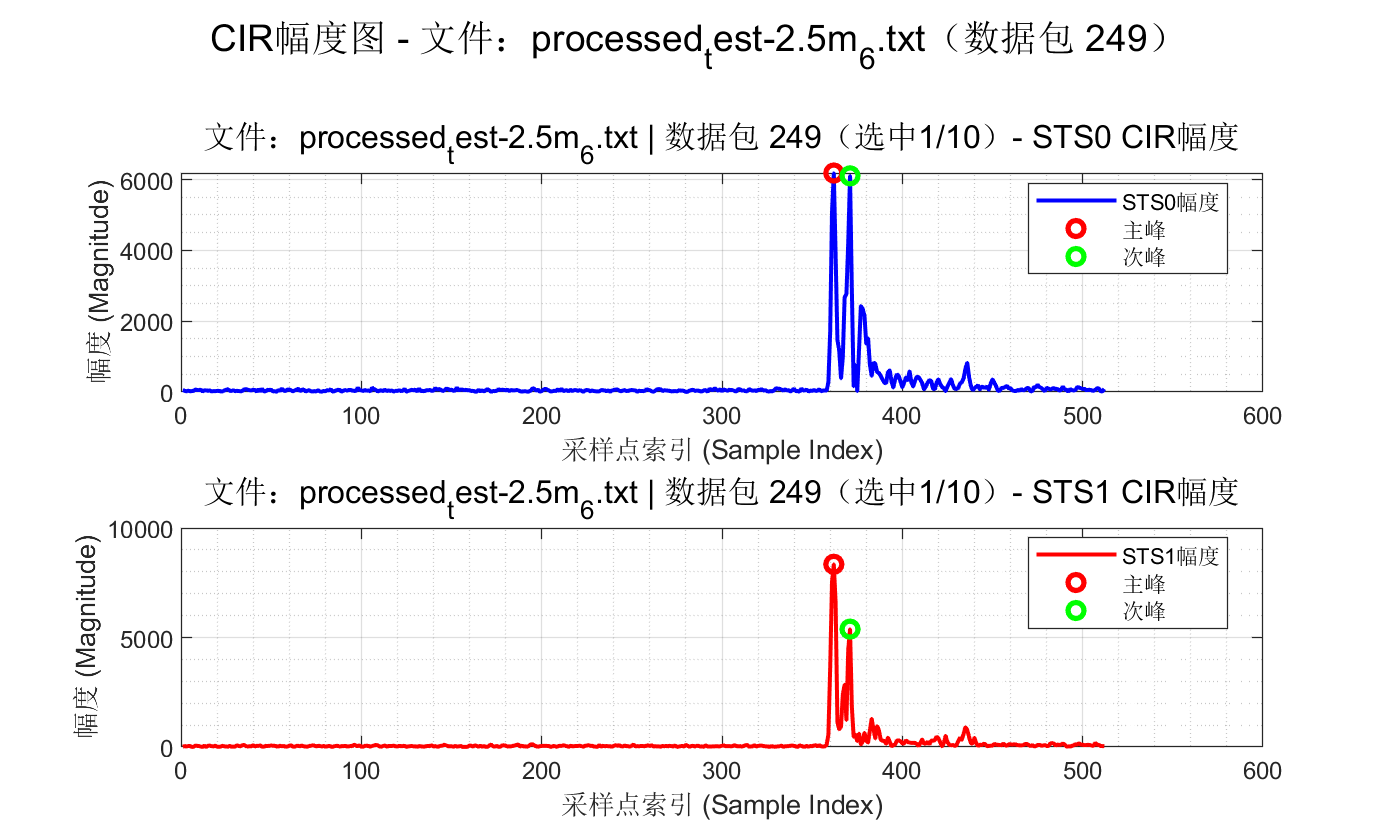

选中的数据包 29 (文件: processed_test-2.5m_6.txt):


  直射径角度: -41.44°


  反射径角度: -6.81°


  主次峰距离: 9.00 采样点


  主峰位置: 359, 次峰位置: 368


  主峰幅度: 6075.68, 次峰幅度: 5625.30



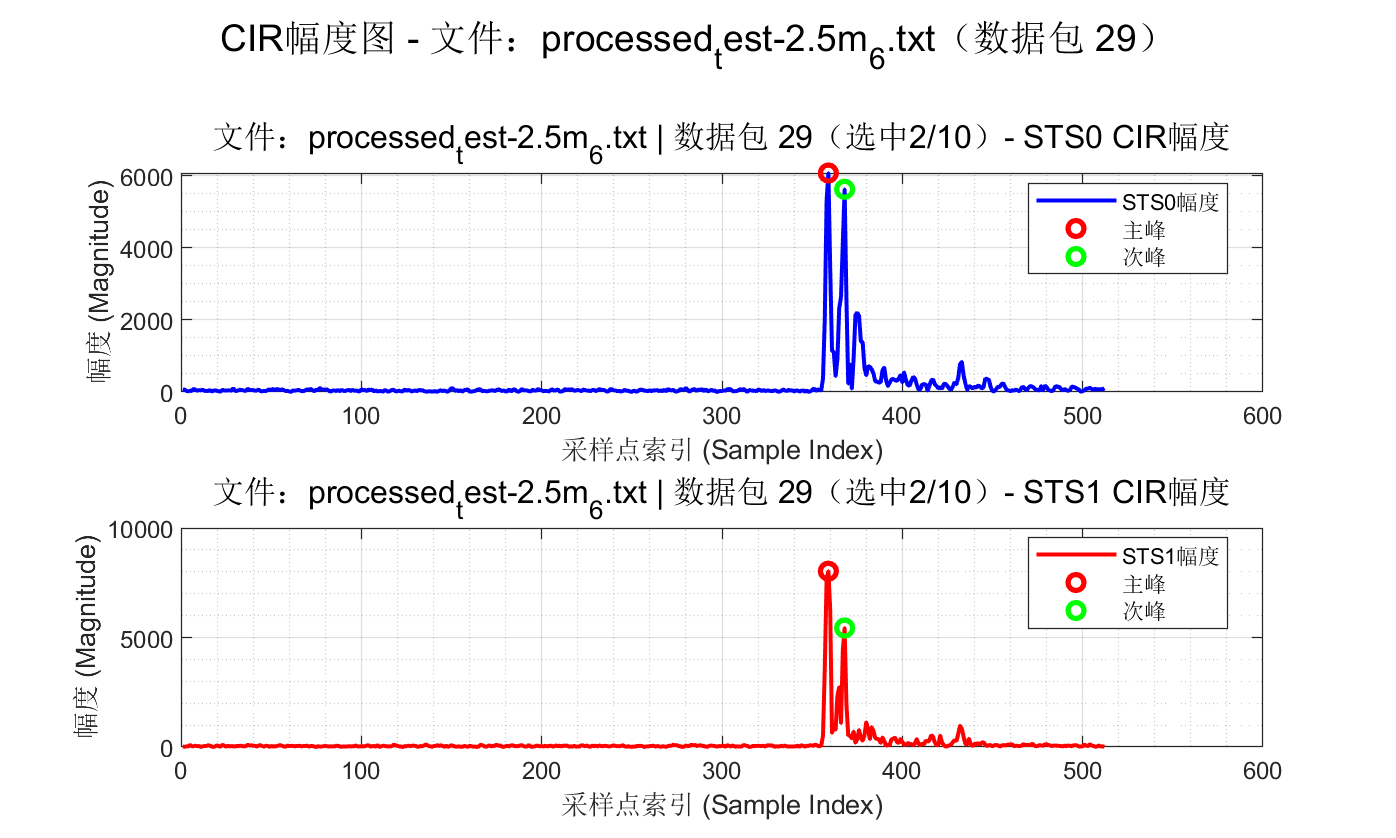

选中的数据包 277 (文件: processed_test-2.5m_6.txt):


  直射径角度: -41.34°


  反射径角度: -7.67°


  主次峰距离: 9.00 采样点


  主峰位置: 356, 次峰位置: 365


  主峰幅度: 4239.89, 次峰幅度: 3905.99



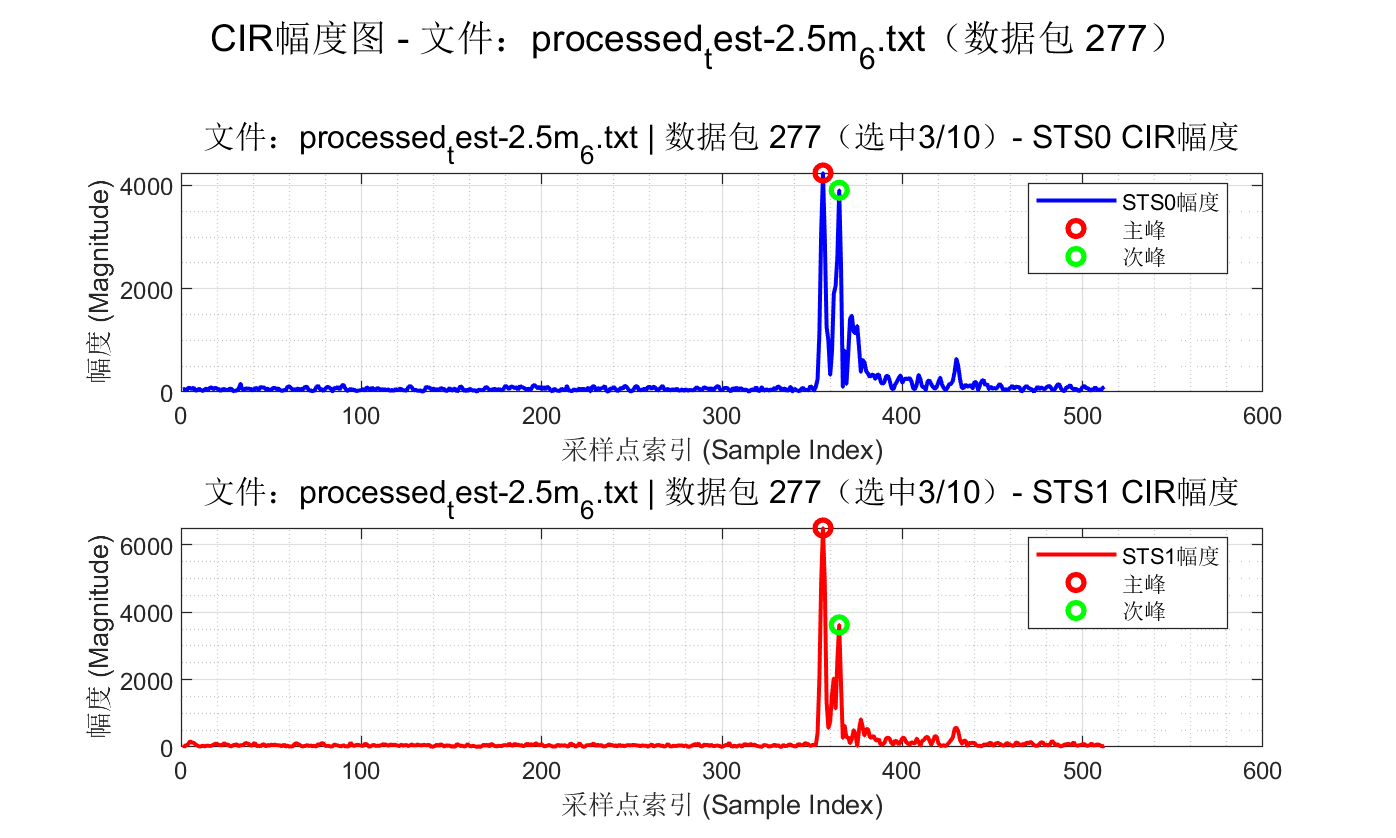

选中的数据包 167 (文件: processed_test-2.5m_6.txt):


  直射径角度: -42.54°


  反射径角度: -8.91°


  主次峰距离: 9.00 采样点


  主峰位置: 357, 次峰位置: 366


  主峰幅度: 6300.21, 次峰幅度: 6000.88



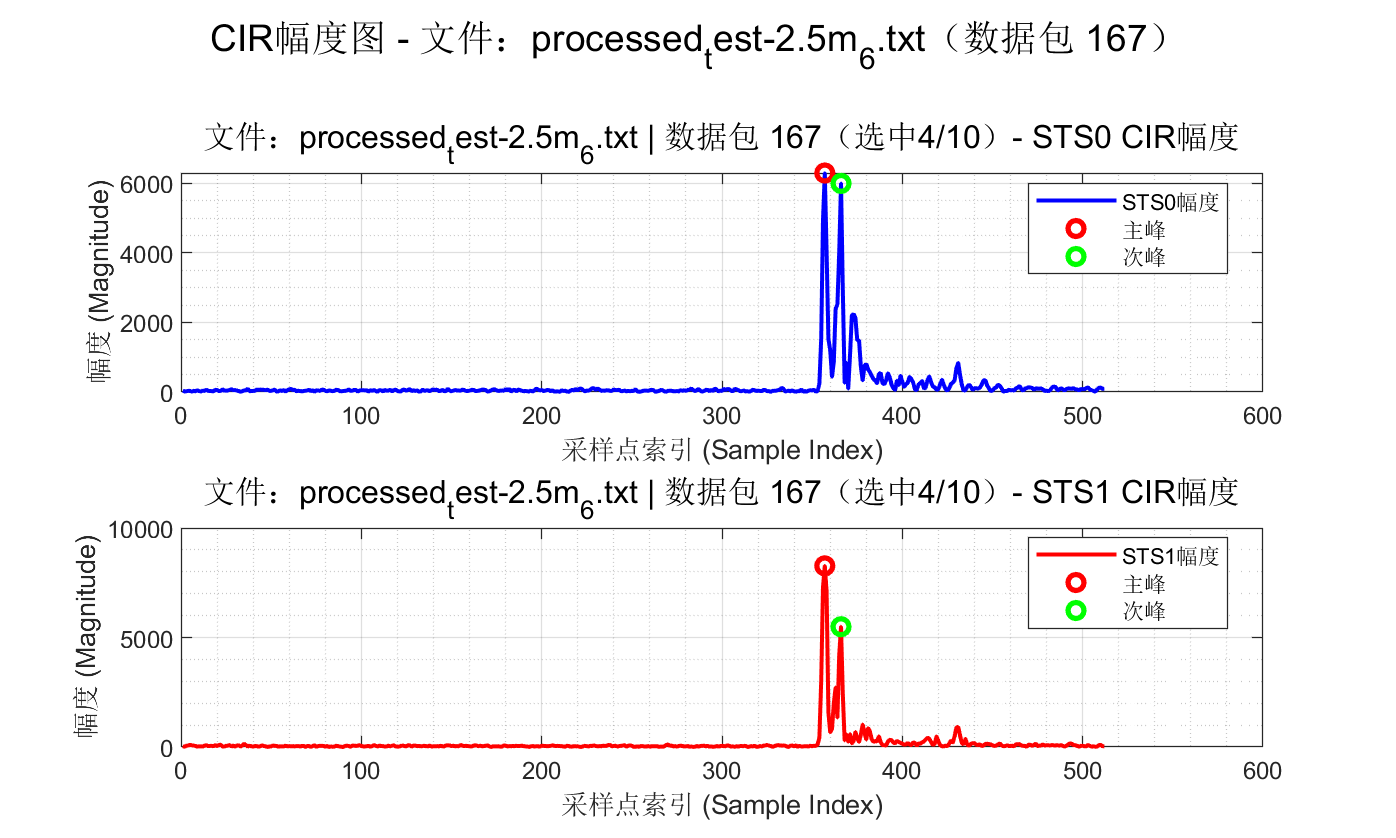

选中的数据包 293 (文件: processed_test-2.5m_6.txt):


  直射径角度: -43.31°


  反射径角度: -11.26°


  主次峰距离: 9.00 采样点


  主峰位置: 362, 次峰位置: 371


  主峰幅度: 6096.38, 次峰幅度: 5946.35



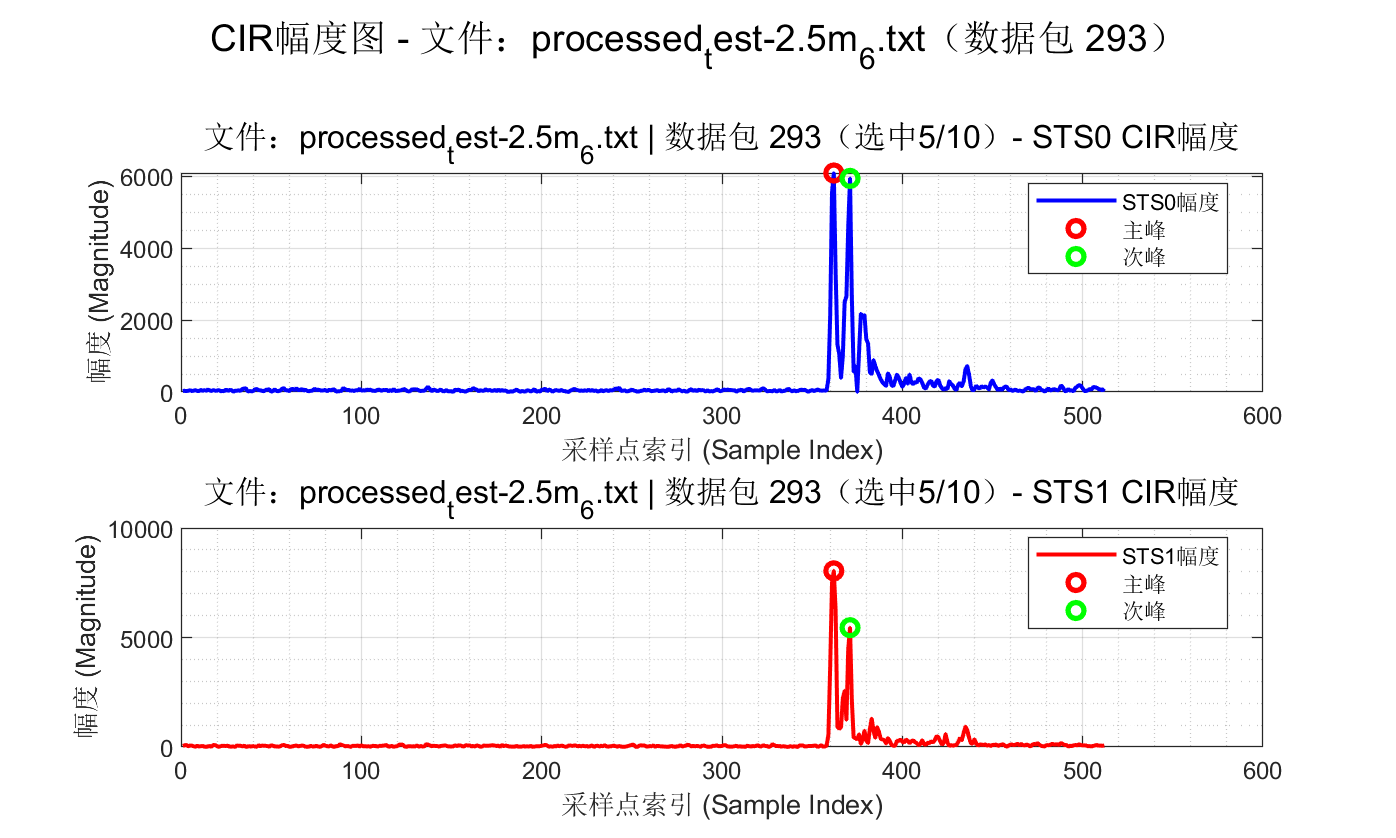

选中的数据包 193 (文件: processed_test-2.5m_6.txt):


  直射径角度: -39.41°


  反射径角度: -2.41°


  主次峰距离: 10.00 采样点


  主峰位置: 359, 次峰位置: 369


  主峰幅度: 5857.40, 次峰幅度: 5351.52



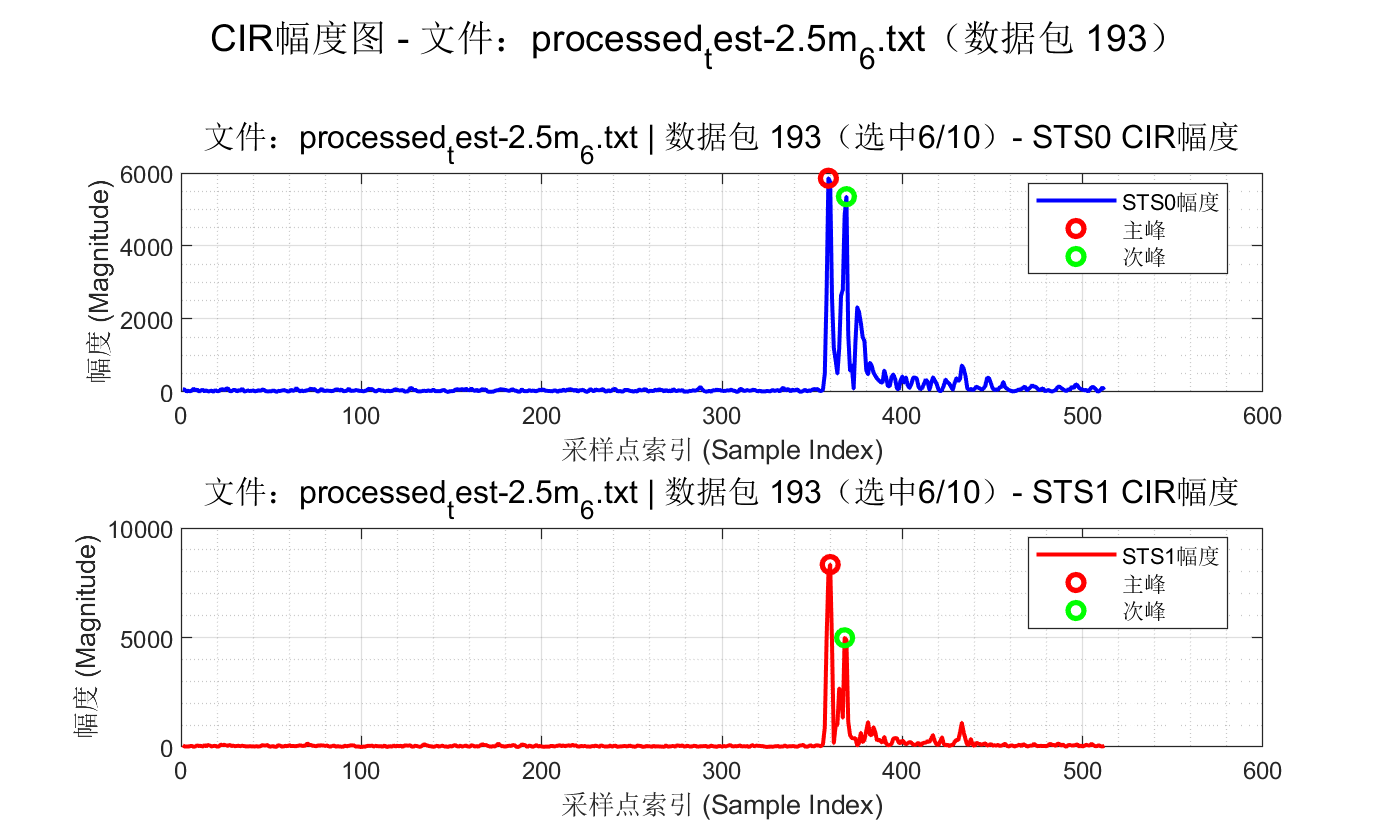

选中的数据包 279 (文件: processed_test-2.5m_6.txt):


  直射径角度: -44.93°


  反射径角度: -9.50°


  主次峰距离: 9.00 采样点


  主峰位置: 361, 次峰位置: 370


  主峰幅度: 6198.37, 次峰幅度: 5845.65



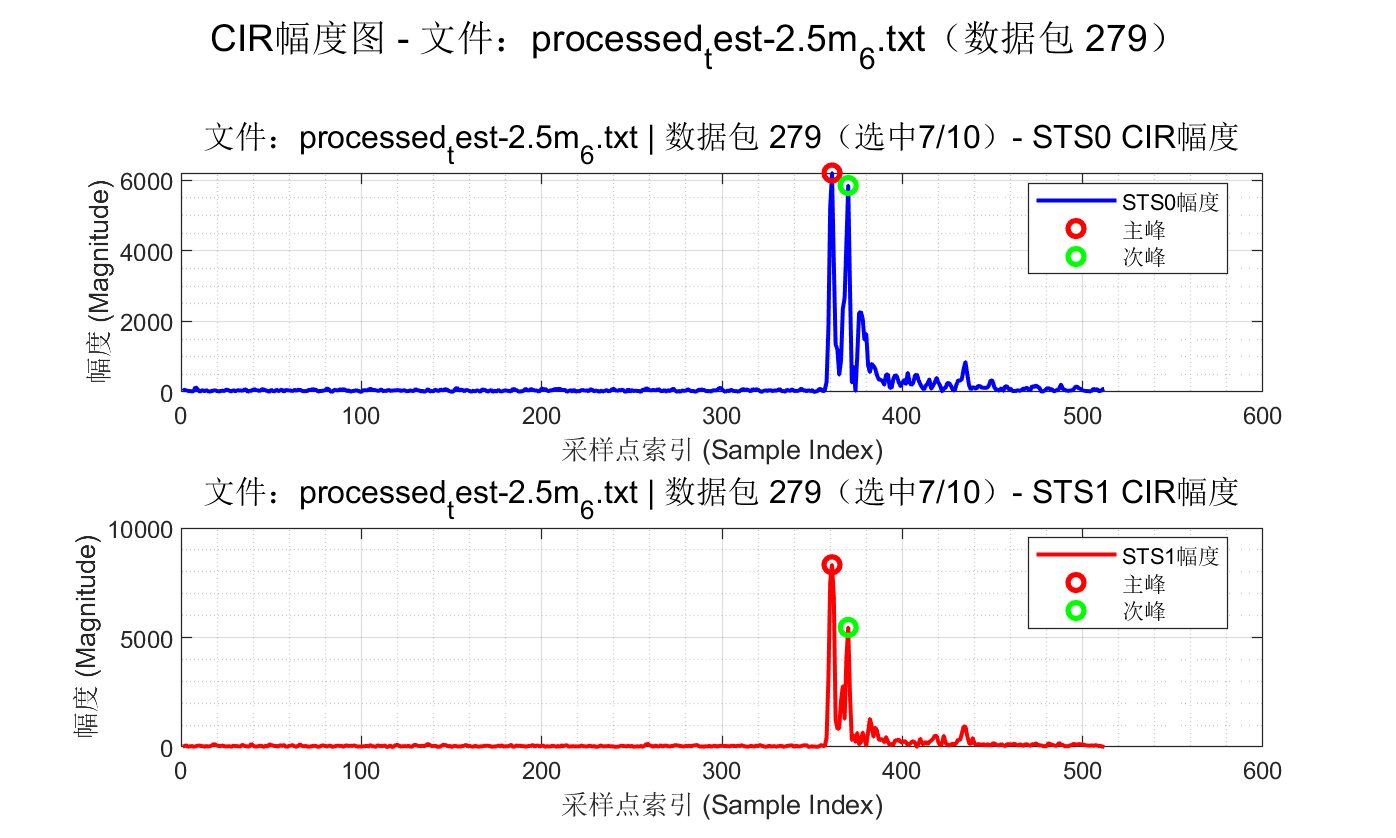

选中的数据包 85 (文件: processed_test-2.5m_6.txt):


  直射径角度: -44.39°


  反射径角度: -10.50°


  主次峰距离: 9.00 采样点


  主峰位置: 356, 次峰位置: 365


  主峰幅度: 6186.00, 次峰幅度: 5881.20



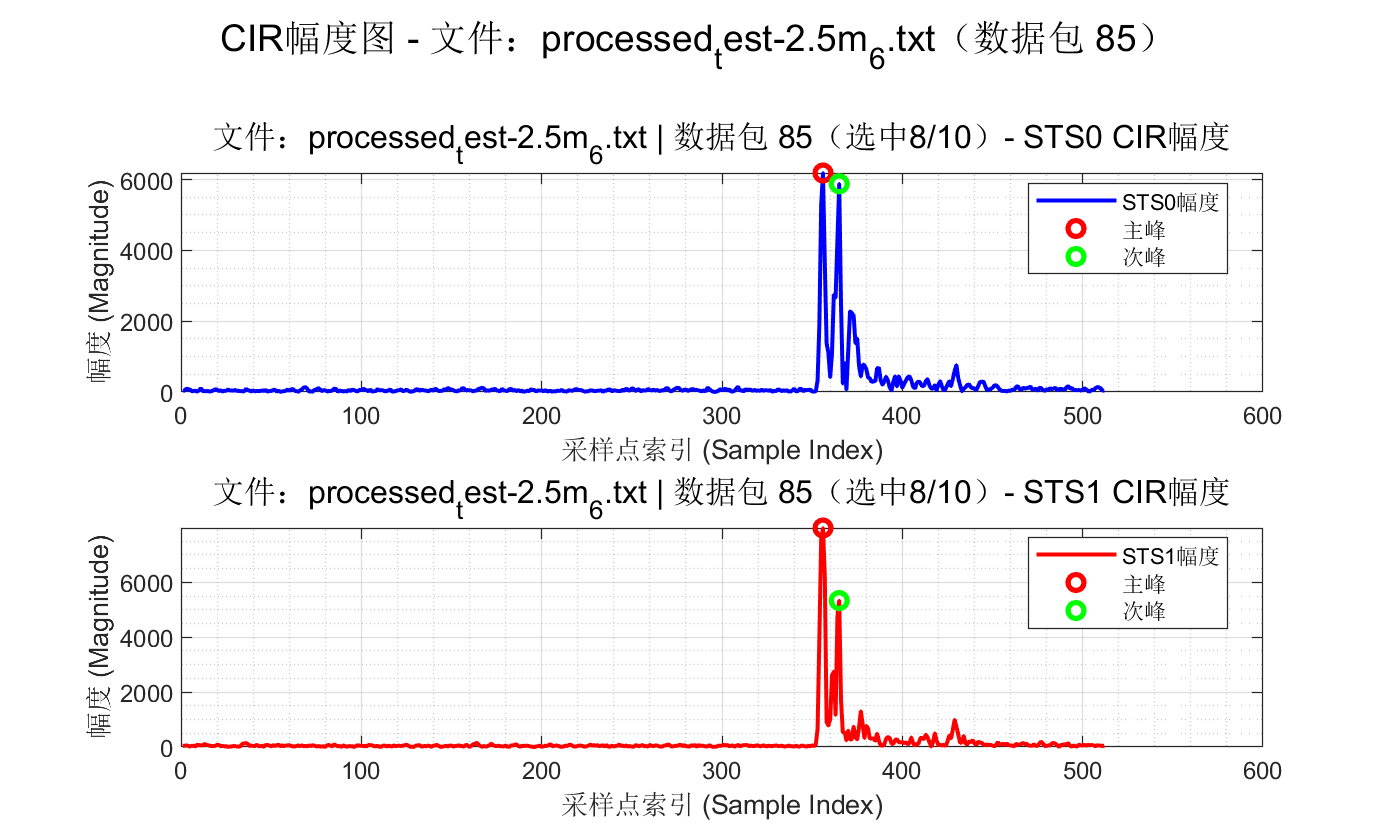

选中的数据包 295 (文件: processed_test-2.5m_6.txt):


  直射径角度: -39.65°


  反射径角度: -6.56°


  主次峰距离: 9.00 采样点


  主峰位置: 360, 次峰位置: 369


  主峰幅度: 6084.48, 次峰幅度: 5362.56



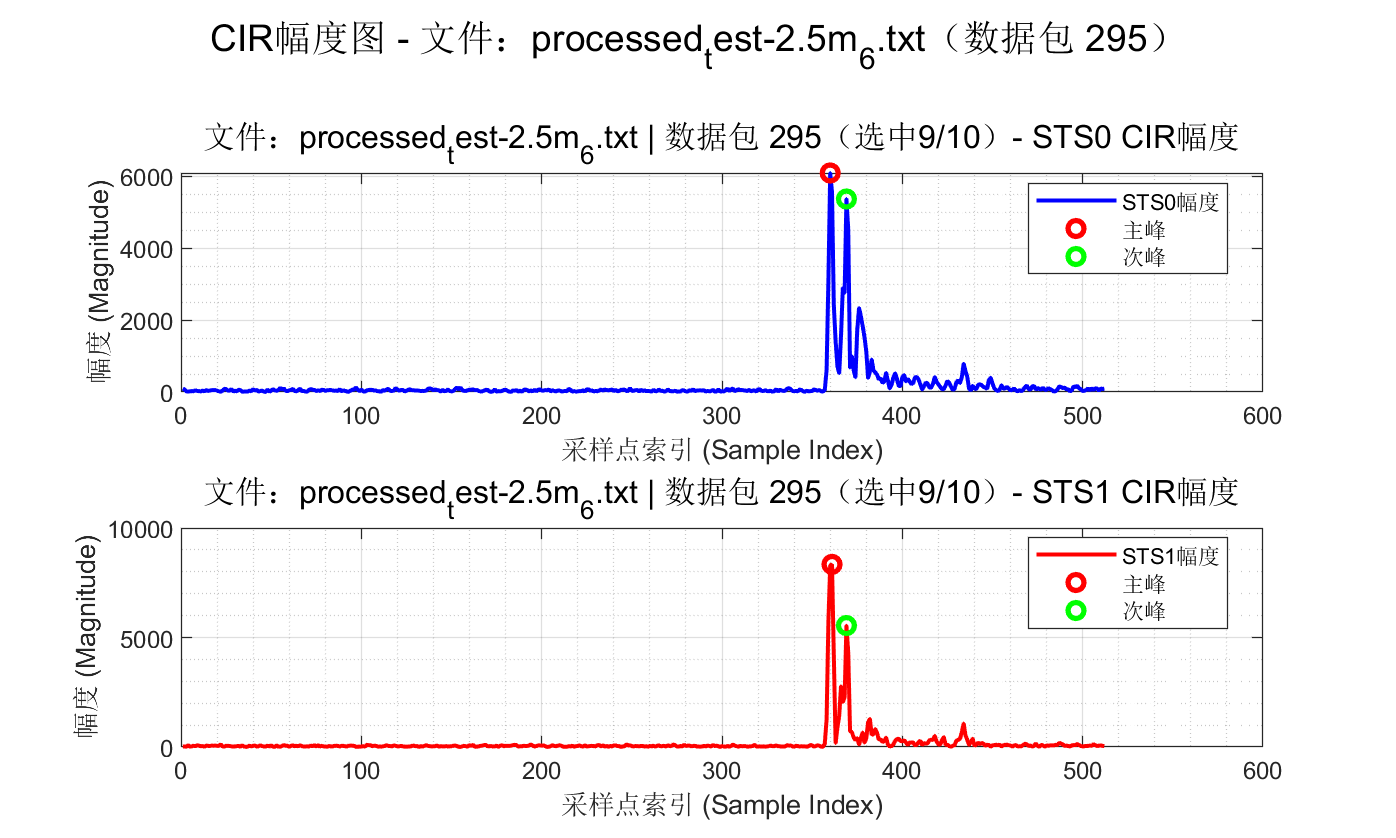

选中的数据包 39 (文件: processed_test-2.5m_6.txt):


  直射径角度: -37.41°


  反射径角度: -6.63°


  主次峰距离: 9.00 采样点


  主峰位置: 361, 次峰位置: 370


  主峰幅度: 6036.85, 次峰幅度: 5603.31



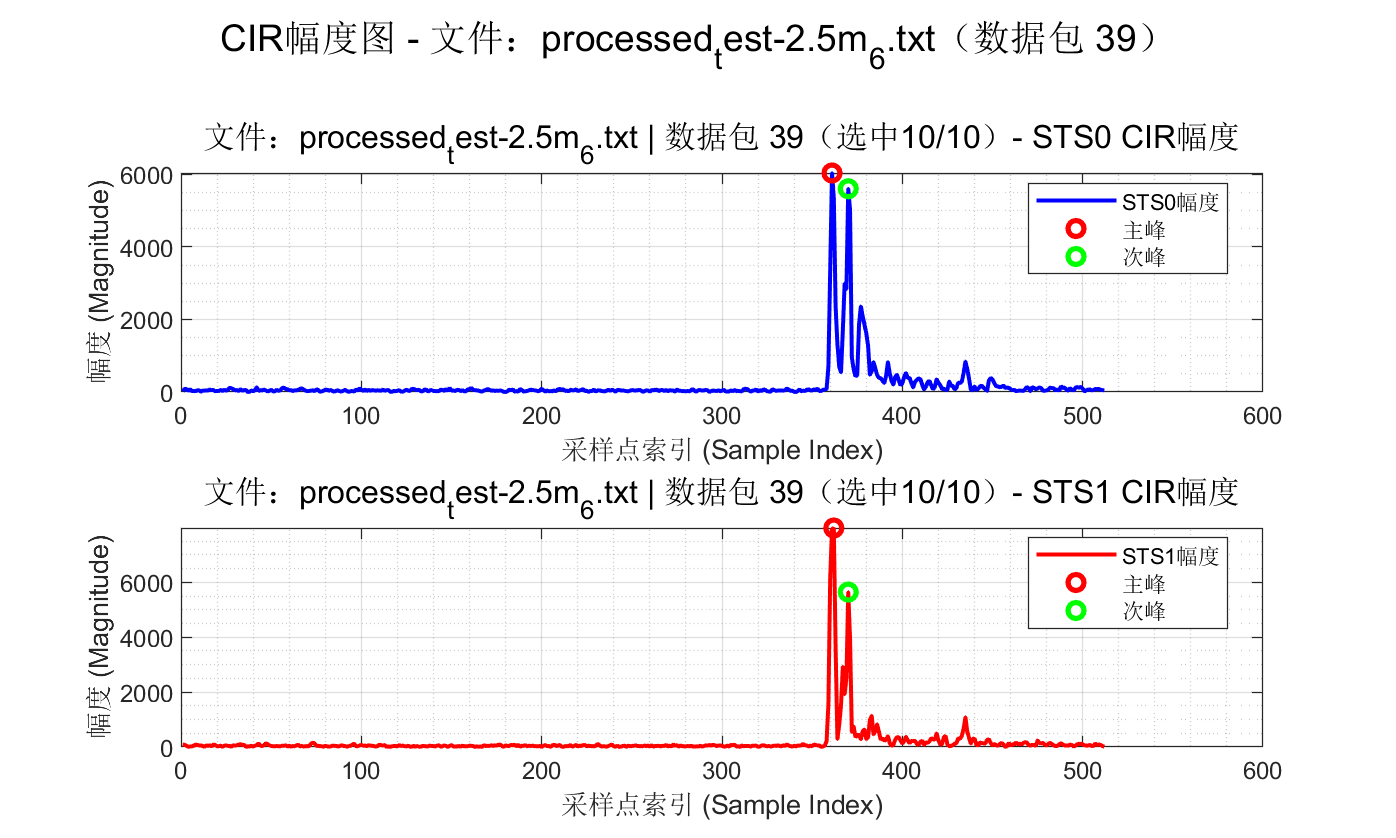

直射径角度标准差 2.83° <= 15°，跳过聚类分析


文件 processed_test-2.5m_6.txt 统计:


  主峰 - PDOA均值: -2.1480, 标准差: 0.1134


  主峰 - 角度均值: -43.20°, 标准差: 2.83°


  次峰 - PDOA均值: -0.4027, 标准差: 0.1197


  次峰 - 角度均值: -7.37°, 标准差: 2.20°


  主次峰距离均值: 9.08 采样点, 标准差: 0.28


  数据点数: 153



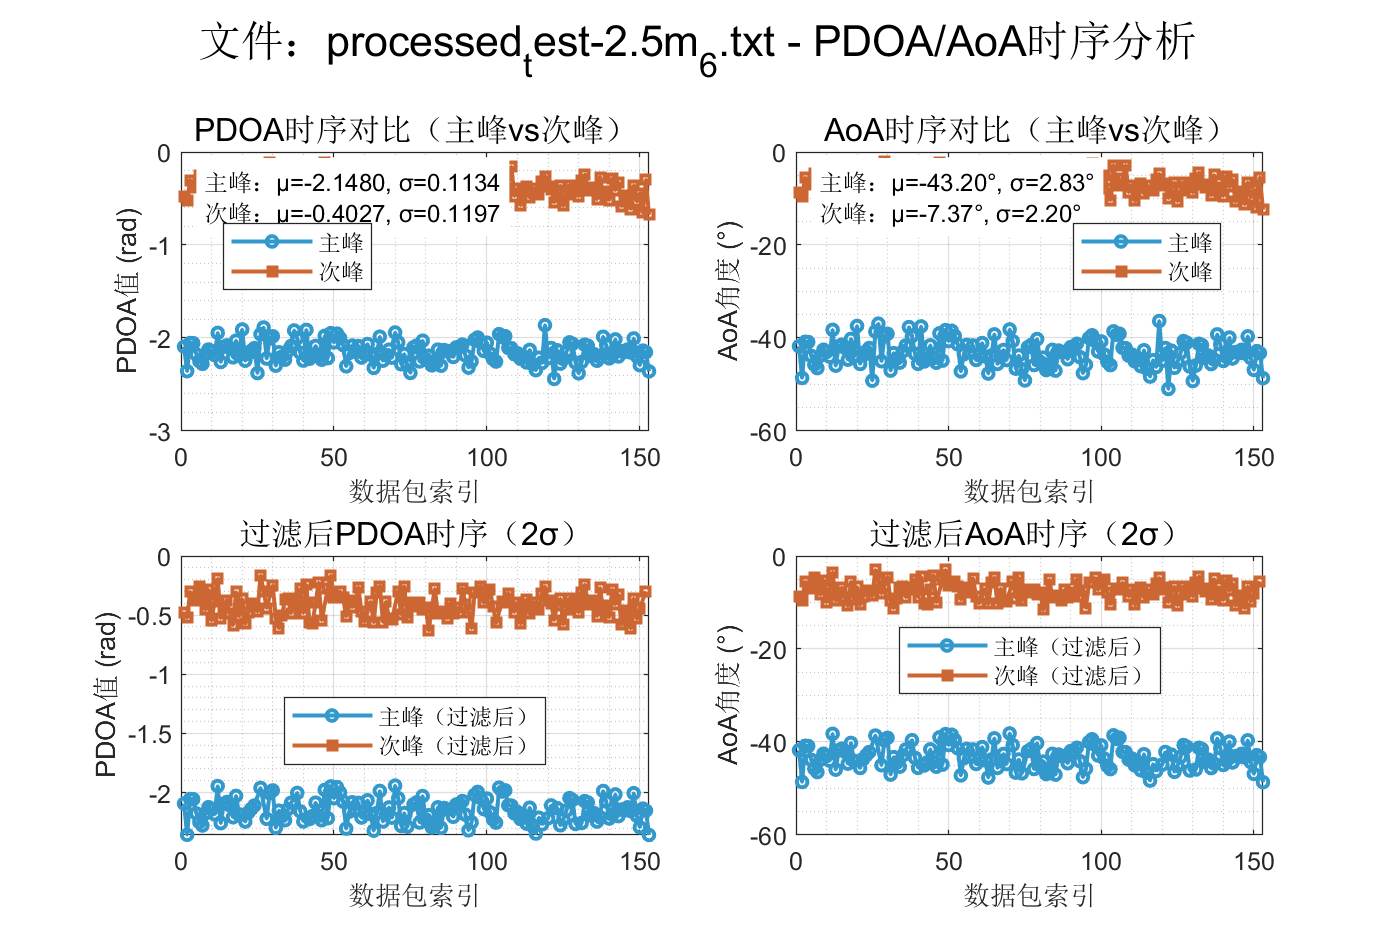

文件 processed_test-2.5m_6.txt 过滤后统计（2σ）:


  主峰PDOA：均值=-2.1499, 标准差=0.0987, 有效点数=144


  次峰PDOA：均值=-0.4119, 标准差=0.1037, 有效点数=144


  主峰AoA：均值=-43.23°, 标准差=2.47°, 有效点数=144


  次峰AoA：均值=-7.54°, 标准差=1.91°, 有效点数=144




% 循环处理每个文件
for file_idx = 6:6
    filename = fullfile(data_folder, file_list(file_idx).name);
    fprintf('正在处理文件: %s\n', filename);

    % 检查文件是否存在
    if ~exist(filename, 'file')
        fprintf('文件不存在: %s\n', filename);
        continue;
    end
    
    fid = fopen(filename, 'r');
    rawData = textscan(fid, '%s', 'Delimiter', '\n');
    fclose(fid);
    
    lines = rawData{1};
    
    % 初始化存储变量
    sn_len = [];
    Ipatov_CIR = [];
    STS0_CIR = [];
    STS1_CIR = [];

    % 状态标志
    current_mode = '';
    inside_CIR_block = false;
    
    % 解析文件内容
    for i = 1:length(lines)
        line = strtrim(lines{i});
        
        if contains(line, 'Sequence Number')
            tokens = regexp(line, 'Sequence Number[:\s]+(\d+)', 'tokens');
            if ~isempty(tokens)
                sn_len = [sn_len, str2double(tokens{1}{1})];
            end
        end
        
        % 检测 CIR 类型标志
        if contains(line, 'Printing Ipatov CIR')
            current_mode = 'Ipatov';
            inside_CIR_block = false;
        elseif contains(line, 'Printing STS0 CIR')
            current_mode = 'STS0';
            inside_CIR_block = false;
        elseif contains(line, 'Printing STS1 CIR')
            current_mode = 'STS1';
            inside_CIR_block = false;
        end
        
        % 检测数据块边界
        if contains(line, '_________________________________')
            inside_CIR_block = ~inside_CIR_block;
            continue;
        end
        
        % 提取CIR数据
        if inside_CIR_block
            data_tokens = regexp(line, '(-?\d+),(-?\d+)', 'tokens');
            if ~isempty(data_tokens)
                I_val = str2double(data_tokens{1}{1});
                Q_val = str2double(data_tokens{1}{2});
                complex_val = I_val + 1j * Q_val;
                
                if strcmp(current_mode, 'Ipatov')
                    Ipatov_CIR(end+1, 1) = complex_val;
                elseif strcmp(current_mode, 'STS0')
                    STS0_CIR(end+1, 1) = complex_val;
                elseif strcmp(current_mode, 'STS1')
                    STS1_CIR(end+1, 1) = complex_val;
                end
            end
        end
    end
    
    % 重新组织CIR数据
    if length(STS0_CIR) >= 512 && length(STS1_CIR) >= 512
        packets_num = floor(length(STS0_CIR)/512);
        STS0_CIR = reshape(STS0_CIR(1:512 * packets_num), 512, packets_num).';
        STS1_CIR = reshape(STS1_CIR(1:512 * packets_num), 512, packets_num).';
        
        % 如果包数为奇数，丢弃最后一行
        if mod(packets_num, 2) ~= 0
            STS0_CIR(end, :) = [];
            STS1_CIR(end, :) = [];
            packets_num = packets_num - 1;
        end
        
        % 初始化当前文件的变量
        aoa_pdoa_values_main = [];
        aoa_degree_values_main = [];
        aoa_pdoa_values_secondary = [];
        aoa_degree_values_secondary = [];
        peak_distance_values = [];
        valid_packet_indices = [];
        selected_packet_indices = [];
        
        % 第一步：先遍历所有数据包，收集有效索引
        for i = 1:packets_num
            STS0_data = STS0_CIR(i,:);  
            STS1_data = STS1_CIR(i,:);
            
            STS0_magnitude = abs(STS0_data);
            STS1_magnitude = abs(STS1_data);
            
            threshold = 0.1;
            min_peak_distance = 2;
            
            % 找峰值
            [peaks_STS0, locs_STS0] = findpeaks(STS0_magnitude, 'MinPeakHeight', threshold * max(STS0_magnitude), 'MinPeakDistance', min_peak_distance);
            [peaks_STS1, locs_STS1] = findpeaks(STS1_magnitude, 'MinPeakHeight', threshold * max(STS1_magnitude), 'MinPeakDistance', min_peak_distance);
            
            % 检查是否找到足够的峰值
            if length(locs_STS0) < 2 || length(locs_STS1) < 2
                continue;
            end
            
            % ==================== 新的找峰算法 ====================
            % 对于STS0：找到主峰（第一个峰）
            peak_index1_STS0 = locs_STS0(1);
            main_peak_magnitude_STS0 = STS0_magnitude(peak_index1_STS0);
            
            % 寻找主峰前后3个点内幅度大于主峰70%的峰
            search_range = 3;
            threshold_ratio = 0.5;
            
            candidate_peaks_STS0 = [];
            candidate_locs_STS0 = [];
            
            % 检查主峰前后的峰值
            for j = 1:length(locs_STS0)
                if locs_STS0(j) ~= peak_index1_STS0 && ...
                   abs(locs_STS0(j) - peak_index1_STS0) <= search_range && ...
                   STS0_magnitude(locs_STS0(j)) >= threshold_ratio * main_peak_magnitude_STS0
                    candidate_peaks_STS0(end+1) = STS0_magnitude(locs_STS0(j));
                    candidate_locs_STS0(end+1) = locs_STS0(j);
                end
            end
            
            if ~isempty(candidate_peaks_STS0)
                % 选择幅度最大的候选峰
                [~, max_idx] = max(candidate_peaks_STS0);
                peak_index2_STS0 = candidate_locs_STS0(max_idx);
            else
                % 如果没有符合条件的候选峰，选择主峰后幅度最高的峰
                post_main_peaks_STS0 = locs_STS0(locs_STS0 > peak_index1_STS0);
                if isempty(post_main_peaks_STS0)
                    continue;
                end
                [~, max_idx] = max(STS0_magnitude(post_main_peaks_STS0));
                peak_index2_STS0 = post_main_peaks_STS0(max_idx);
            end
            
            % 对于STS1：同样处理
            peak_index1_STS1 = locs_STS1(1);
            main_peak_magnitude_STS1 = STS1_magnitude(peak_index1_STS1);
            
            candidate_peaks_STS1 = [];
            candidate_locs_STS1 = [];
            
            for j = 1:length(locs_STS1)
                if locs_STS1(j) ~= peak_index1_STS1 && ...
                   abs(locs_STS1(j) - peak_index1_STS1) <= search_range && ...
                   STS1_magnitude(locs_STS1(j)) >= threshold_ratio * main_peak_magnitude_STS1
                    candidate_peaks_STS1(end+1) = STS1_magnitude(locs_STS1(j));
                    candidate_locs_STS1(end+1) = locs_STS1(j);
                end
            end
            
            if ~isempty(candidate_peaks_STS1)
                [~, max_idx] = max(candidate_peaks_STS1);
                peak_index2_STS1 = candidate_locs_STS1(max_idx);
            else
                post_main_peaks_STS1 = locs_STS1(locs_STS1 > peak_index1_STS1);
                if isempty(post_main_peaks_STS1)
                    continue;
                end
                [~, max_idx] = max(STS1_magnitude(post_main_peaks_STS1));
                peak_index2_STS1 = post_main_peaks_STS1(max_idx);
            end
            % ==================== 新的找峰算法结束 ====================
            
            % 计算主峰和次峰之间的距离
            peak_distance = abs(peak_index2_STS0 - peak_index1_STS0);
            if peak_distance > 15
                continue;
            end  
            
            % 幅度差值判断条件
            a_STS0 = STS0_magnitude(peak_index1_STS0) - STS0_magnitude(peak_index2_STS0);
            a_STS1 = STS1_magnitude(peak_index1_STS1) - STS1_magnitude(peak_index2_STS1);
            
            if sign(a_STS0) ~= sign(a_STS1)
                continue;
            end
            
            a_abs = abs(a_STS0);
            b_abs = abs(a_STS1);
            
            if a_abs == 0 || b_abs == 0
                continue;
            end
            
            min_amplitude_diff = min(a_abs, b_abs);
            amplitude_ratio = abs(a_abs - b_abs) / min_amplitude_diff;
            
            if amplitude_ratio >= 500 %这里的参数可以调整
                continue;
            end
            
            % 记录有效数据包索引
            valid_packet_indices(end+1) = i;
            
            % 计算PDOA和AoA
            % 主峰相位差计算（直射径）
            STS0_phase_main = angle(STS0_data(peak_index1_STS1));
            STS1_phase_main = angle(STS1_data(peak_index1_STS1));
            phase_difference_main = STS1_phase_main - STS0_phase_main - phase_offset;
            phase_difference_main = mod(phase_difference_main + pi, 2*pi) - pi;
            
            theta_radians_main = asin(phase_difference_main * c / (2 * pi * antennaSpacing * frequency));
            theta_degrees_main = rad2deg(theta_radians_main);
            
            % 次强峰相位差计算（反射径）
            STS0_phase_secondary = angle(STS0_data(peak_index2_STS1));
            STS1_phase_secondary = angle(STS1_data(peak_index2_STS1));
            phase_difference_secondary = STS1_phase_secondary - STS0_phase_secondary - phase_offset;
            phase_difference_secondary = mod(phase_difference_secondary + pi, 2*pi) - pi;
            
            theta_radians_secondary = asin(phase_difference_secondary * c / (2 * pi * antennaSpacing * frequency));
            theta_degrees_secondary = rad2deg(theta_radians_secondary);
            
            % 注意：这里移除了对所有数据包的打印，只对选中的10个包打印
            aoa_pdoa_values_main(end+1) = phase_difference_main;
            aoa_degree_values_main(end+1) = theta_degrees_main;
            aoa_pdoa_values_secondary(end+1) = phase_difference_secondary;
            aoa_degree_values_secondary(end+1) = theta_degrees_secondary;
            peak_distance_values(end+1) = peak_distance;
        end
        
        % 第二步：从有效数据包中随机选取最多10个绘制CIR图
        if length(valid_packet_indices) > 0
            num_select = min(10, length(valid_packet_indices));
            selected_packet_indices = randsample(valid_packet_indices, num_select, false);
            fprintf('文件 %s 有效数据包数：%d，随机选中 %d 个绘制CIR图（索引：%s）\n', ...
                file_list(file_idx).name, length(valid_packet_indices), num_select, num2str(selected_packet_indices));
            
            % 遍历选中的数据包，绘制CIR图
            for idx = 1:num_select
                i = selected_packet_indices(idx);
                STS0_data = STS0_CIR(i,:);  
                STS1_data = STS1_CIR(i,:);
                
                STS0_magnitude = abs(STS0_data);
                STS1_magnitude = abs(STS1_data);
                
                threshold = 0.1;
                min_peak_distance = 1;
                
                % 重新计算该数据包的峰值
                [peaks_STS0, locs_STS0] = findpeaks(STS0_magnitude, 'MinPeakHeight', threshold * max(STS0_magnitude), 'MinPeakDistance', min_peak_distance);
                [peaks_STS1, locs_STS1] = findpeaks(STS1_magnitude, 'MinPeakHeight', threshold * max(STS1_magnitude), 'MinPeakDistance', min_peak_distance);
                
                % 应用新的找峰算法
                peak_index1_STS0 = locs_STS0(1);
                main_peak_magnitude_STS0 = STS0_magnitude(peak_index1_STS0);
                
                search_range = 3;
                threshold_ratio = 0.5;
                
                candidate_peaks_STS0 = [];
                candidate_locs_STS0 = [];
                
                for j = 1:length(locs_STS0)
                    if locs_STS0(j) ~= peak_index1_STS0 && ...
                       abs(locs_STS0(j) - peak_index1_STS0) <= search_range && ...
                       STS0_magnitude(locs_STS0(j)) >= threshold_ratio * main_peak_magnitude_STS0
                        candidate_peaks_STS0(end+1) = STS0_magnitude(locs_STS0(j));
                        candidate_locs_STS0(end+1) = locs_STS0(j);
                    end
                end
                
                if ~isempty(candidate_peaks_STS0)
                    [~, max_idx] = max(candidate_peaks_STS0);
                    peak_index2_STS0 = candidate_locs_STS0(max_idx);
                else
                    post_main_peaks_STS0 = locs_STS0(locs_STS0 > peak_index1_STS0);
                    if ~isempty(post_main_peaks_STS0)
                        [~, max_idx] = max(STS0_magnitude(post_main_peaks_STS0));
                        peak_index2_STS0 = post_main_peaks_STS0(max_idx);
                    else
                        peak_index2_STS0 = locs_STS0(2);
                    end
                end
                
                peak_index1_STS1 = locs_STS1(1);
                main_peak_magnitude_STS1 = STS1_magnitude(peak_index1_STS1);
                
                candidate_peaks_STS1 = [];
                candidate_locs_STS1 = [];
                
                for j = 1:length(locs_STS1)
                    if locs_STS1(j) ~= peak_index1_STS1 && ...
                       abs(locs_STS1(j) - peak_index1_STS1) <= search_range && ...
                       STS1_magnitude(locs_STS1(j)) >= threshold_ratio * main_peak_magnitude_STS1
                        candidate_peaks_STS1(end+1) = STS1_magnitude(locs_STS1(j));
                        candidate_locs_STS1(end+1) = locs_STS1(j);
                    end
                end
                
                if ~isempty(candidate_peaks_STS1)
                    [~, max_idx] = max(candidate_peaks_STS1);
                    peak_index2_STS1 = candidate_locs_STS1(max_idx);
                else
                    post_main_peaks_STS1 = locs_STS1(locs_STS1 > peak_index1_STS1);
                    if ~isempty(post_main_peaks_STS1)
                        [~, max_idx] = max(STS1_magnitude(post_main_peaks_STS1));
                        peak_index2_STS1 = post_main_peaks_STS1(max_idx);
                    else
                        peak_index2_STS1 = locs_STS1(2);
                    end
                end
                
                % ==================== 新增：仅对选中的10个数据包打印结果 ====================
                % 计算当前选中数据包的PDOA和AoA
                STS0_phase_main = angle(STS0_data(peak_index1_STS1));
                STS1_phase_main = angle(STS1_data(peak_index1_STS1));
                phase_difference_main = STS1_phase_main - STS0_phase_main - phase_offset;
                phase_difference_main = mod(phase_difference_main + pi, 2*pi) - pi;
                
                theta_radians_main = asin(phase_difference_main * c / (2 * pi * antennaSpacing * frequency));
                theta_degrees_main = rad2deg(theta_radians_main);
                
                STS0_phase_secondary = angle(STS0_data(peak_index2_STS1));
                STS1_phase_secondary = angle(STS1_data(peak_index2_STS1));
                phase_difference_secondary = STS1_phase_secondary - STS0_phase_secondary - phase_offset;
                phase_difference_secondary = mod(phase_difference_secondary + pi, 2*pi) - pi;
                
                theta_radians_secondary = asin(phase_difference_secondary * c / (2 * pi * antennaSpacing * frequency));
                theta_degrees_secondary = rad2deg(theta_radians_secondary);
                
                peak_distance = abs(peak_index2_STS0 - peak_index1_STS0);
                
                % 打印选中数据包的结果
                fprintf('选中的数据包 %d (文件: %s):\n', i, file_list(file_idx).name);
                fprintf('  直射径角度: %.2f°\n', theta_degrees_main);
                fprintf('  反射径角度: %.2f°\n', theta_degrees_secondary);
                fprintf('  主次峰距离: %.2f 采样点\n', peak_distance);
                fprintf('  主峰位置: %d, 次峰位置: %d\n', peak_index1_STS0, peak_index2_STS0);
                fprintf('  主峰幅度: %.2f, 次峰幅度: %.2f\n\n', ...
                    STS0_magnitude(peak_index1_STS0), STS0_magnitude(peak_index2_STS0));
                
                % 绘制CIR图
                cir_fig_num = 100 + file_idx * 100 + idx;
                figure(cir_fig_num);
                set(gcf, 'Position', [100 + (file_idx-1)*20 + (idx-1)*50, 100 + (idx-1)*50, 1000, 600]);
                
                % 子图1：STS0 CIR幅度 + 峰值标记
                subplot(2,1,1);
                plot(STS0_magnitude, 'b', 'LineWidth', 1.5);
                hold on;
                plot(peak_index1_STS0, STS0_magnitude(peak_index1_STS0), 'ro', 'MarkerSize', 6, 'LineWidth', 2);
                plot(peak_index2_STS0, STS0_magnitude(peak_index2_STS0), 'go', 'MarkerSize', 6, 'LineWidth', 2);
                hold off;
                title(sprintf('文件：%s | 数据包 %d（选中%d/%d）- STS0 CIR幅度', file_list(file_idx).name, i, idx, num_select), 'FontSize', 12);
                xlabel('采样点索引 (Sample Index)', 'FontSize', 10);
                ylabel('幅度 (Magnitude)', 'FontSize', 10);
                legend('STS0幅度', '主峰', '次峰', 'Location', 'best');
                grid on; grid minor;
                
                % 子图2：STS1 CIR幅度 + 峰值标记
                subplot(2,1,2);
                plot(STS1_magnitude, 'r', 'LineWidth', 1.5);
                hold on;
                plot(peak_index1_STS1, STS1_magnitude(peak_index1_STS1), 'ro', 'MarkerSize', 6, 'LineWidth', 2);
                plot(peak_index2_STS1, STS1_magnitude(peak_index2_STS1), 'go', 'MarkerSize', 6, 'LineWidth', 2);
                hold off;
                title(sprintf('文件：%s | 数据包 %d（选中%d/%d）- STS1 CIR幅度', file_list(file_idx).name, i, idx, num_select), 'FontSize', 12);
                xlabel('采样点索引 (Sample Index)', 'FontSize', 10);
                ylabel('幅度 (Magnitude)', 'FontSize', 10);
                legend('STS1幅度', '主峰', '次峰', 'Location', 'best');
                grid on; grid minor;
                
                sgtitle(sprintf('CIR幅度图 - 文件：%s（数据包 %d）', file_list(file_idx).name, i), 'FontSize', 14);
            end
        else
            fprintf('文件 %s 无有效数据包，跳过CIR图绘制\n', file_list(file_idx).name);
        end
        
        % ==================== 新增：直射径角度聚类分析模块 ====================
        % 检查直射径角度标准差是否大于15度
        if ~isempty(aoa_degree_values_main) && std(aoa_degree_values_main) > 15
            fprintf('直射径角度标准差 %.2f° > 15°，进行聚类分析...\n', std(aoa_degree_values_main));
            
            % 计算反射径角度的平均值
            mean_secondary = mean(aoa_degree_values_secondary);
            
            % 使用kmeans聚类将直射径角度分为2类
            try
                [cluster_idx, cluster_centers] = kmeans(aoa_degree_values_main(:), 2);
                
                % 计算每个聚类中心与反射径平均角度的距离
                dist_to_secondary = abs(cluster_centers - mean_secondary);
                
                % 找到距离反射径平均角度最近的聚类
                [~, closest_cluster] = min(dist_to_secondary);
                
                % 保留距离反射径平均角度较远的聚类
                keep_indices = (cluster_idx ~= closest_cluster);
                
                % 记录剔除前后的数据量
                original_count = length(aoa_degree_values_main);
                new_count = sum(keep_indices);
                
                fprintf('聚类分析结果:\n');
                fprintf('  聚类中心1: %.2f°, 距离反射径: %.2f°\n', cluster_centers(1), dist_to_secondary(1));
                fprintf('  聚类中心2: %.2f°, 距离反射径: %.2f°\n', cluster_centers(2), dist_to_secondary(2));
                fprintf('  剔除聚类 %d (距离反射径最近)\n', closest_cluster);
                fprintf('  数据点数量: %d -> %d (剔除 %d 个)\n', ...
                    original_count, new_count, original_count - new_count);
                
                % 更新所有相关数组，只保留被选中的数据
                if new_count > 0
                    aoa_pdoa_values_main = aoa_pdoa_values_main(keep_indices);
                    aoa_degree_values_main = aoa_degree_values_main(keep_indices);
                    aoa_pdoa_values_secondary = aoa_pdoa_values_secondary(keep_indices);
                    aoa_degree_values_secondary = aoa_degree_values_secondary(keep_indices);
                    peak_distance_values = peak_distance_values(keep_indices);
                    valid_packet_indices = valid_packet_indices(keep_indices);
                    
                    fprintf('  聚类后直射径角度标准差: %.2f°\n', std(aoa_degree_values_main));
                else
                    fprintf('  警告：聚类后无有效数据保留！\n');
                    % 如果聚类后没有数据，清空所有数组
                    aoa_pdoa_values_main = [];
                    aoa_degree_values_main = [];
                    aoa_pdoa_values_secondary = [];
                    aoa_degree_values_secondary = [];
                    peak_distance_values = [];
                    valid_packet_indices = [];
                end
                
            catch ME
                fprintf('聚类分析失败: %s\n', ME.message);
                fprintf('跳过聚类处理，使用原始数据\n');
            end
        else
            if ~isempty(aoa_degree_values_main)
                fprintf('直射径角度标准差 %.2f° <= 15°，跳过聚类分析\n', std(aoa_degree_values_main));
            end
        end
        % ==================== 聚类分析模块结束 ====================
        
        % 存储当前文件的结果
        if ~isempty(aoa_pdoa_values_main)
            % 存储到总体结果
            all_main_pdoa = [all_main_pdoa; aoa_pdoa_values_main(:)];
            all_main_degree = [all_main_degree; aoa_degree_values_main(:)];
            all_secondary_pdoa = [all_secondary_pdoa; aoa_pdoa_values_secondary(:)];
            all_secondary_degree = [all_secondary_degree; aoa_degree_values_secondary(:)];
            all_peak_distances = [all_peak_distances; peak_distance_values(:)];
            
            % 存储每个文件的详细结果
            all_file_results(file_idx).filename = file_list(file_idx).name;
            all_file_results(file_idx).main_pdoa = aoa_pdoa_values_main;
            all_file_results(file_idx).main_degree = aoa_degree_values_main;
            all_file_results(file_idx).secondary_pdoa = aoa_pdoa_values_secondary;
            all_file_results(file_idx).secondary_degree = aoa_degree_values_secondary;
            all_file_results(file_idx).peak_distances = peak_distance_values;
            all_file_results(file_idx).packets_num = packets_num;
            all_file_results(file_idx).valid_packet_indices = valid_packet_indices;
            all_file_results(file_idx).selected_packet_indices = selected_packet_indices;
            
            % 显示当前文件统计结果
            fprintf('文件 %s 统计:\n', file_list(file_idx).name);
            fprintf('  主峰 - PDOA均值: %.4f, 标准差: %.4f\n', mean(aoa_pdoa_values_main), std(aoa_pdoa_values_main));
            fprintf('  主峰 - 角度均值: %.2f°, 标准差: %.2f°\n', mean(aoa_degree_values_main), std(aoa_degree_values_main));
            fprintf('  次峰 - PDOA均值: %.4f, 标准差: %.4f\n', mean(aoa_pdoa_values_secondary), std(aoa_pdoa_values_secondary));
            fprintf('  次峰 - 角度均值: %.2f°, 标准差: %.2f°\n', mean(aoa_degree_values_secondary), std(aoa_degree_values_secondary));
            fprintf('  主次峰距离均值: %.2f 采样点, 标准差: %.2f\n', mean(peak_distance_values), std(peak_distance_values));
            fprintf('  数据点数: %d\n\n', length(aoa_pdoa_values_main));

            % 当前文件的PDOA/AoA时序对比图
            time_fig_num = 200 + file_idx;
            figure(time_fig_num);
            set(gcf, 'Position', [300 + (file_idx-1)*20, 300, 1200, 800]);
            time_vec = 1:length(aoa_pdoa_values_main);
            
            % 子图1：主峰vs次峰 PDOA时序
            subplot(2,2,1);
            plot(time_vec, aoa_pdoa_values_main, '-o', 'LineWidth', 1.5, 'Color', [0.2 0.6 0.8], 'MarkerSize', 4); hold on;
            plot(time_vec, aoa_pdoa_values_secondary, '-s', 'LineWidth', 1.5, 'Color', [0.8 0.4 0.2], 'MarkerSize', 4);
            title('PDOA时序对比（主峰vs次峰）', 'FontSize', 12);
            xlabel('数据包索引', 'FontSize', 10);
            ylabel('PDOA值 (rad)', 'FontSize', 10);
            legend('主峰', '次峰', 'Location', 'best');
            grid on; grid minor;
            
            mean_pdoa_main = mean(aoa_pdoa_values_main);
            std_pdoa_main = std(aoa_pdoa_values_main);
            mean_pdoa_sec = mean(aoa_pdoa_values_secondary);
            std_pdoa_sec = std(aoa_pdoa_values_secondary);
            text(0.05, 0.95, sprintf('主峰：μ=%.4f, σ=%.4f\n次峰：μ=%.4f, σ=%.4f', ...
                mean_pdoa_main, std_pdoa_main, mean_pdoa_sec, std_pdoa_sec), ...
                'Units', 'normalized', 'VerticalAlignment', 'top', 'FontSize', 9, 'BackgroundColor', 'white');
            
            % 子图2：主峰vs次峰 AoA时序
            subplot(2,2,2);
            plot(time_vec, aoa_degree_values_main, '-o', 'LineWidth', 1.5, 'Color', [0.2 0.6 0.8], 'MarkerSize', 4); hold on;
            plot(time_vec, aoa_degree_values_secondary, '-s', 'LineWidth', 1.5, 'Color', [0.8 0.4 0.2], 'MarkerSize', 4);
            title('AoA时序对比（主峰vs次峰）', 'FontSize', 12);
            xlabel('数据包索引', 'FontSize', 10);
            ylabel('AoA角度 (°)', 'FontSize', 10);
            legend('主峰', '次峰', 'Location', 'best');
            grid on; grid minor;
            
            mean_degree_main = mean(aoa_degree_values_main);
            std_degree_main = std(aoa_degree_values_main);
            mean_degree_sec = mean(aoa_degree_values_secondary);
            std_degree_sec = std(aoa_degree_values_secondary);
            text(0.05, 0.95, sprintf('主峰：μ=%.2f°, σ=%.2f°\n次峰：μ=%.2f°, σ=%.2f°', ...
                mean_degree_main, std_degree_main, mean_degree_sec, std_degree_sec), ...
                'Units', 'normalized', 'VerticalAlignment', 'top', 'FontSize', 9, 'BackgroundColor', 'white');
            
            % 子图3：过滤后PDOA时序（2倍标准差）
            subplot(2,2,3);
            threshold = 2;
            valid_main = abs(aoa_pdoa_values_main - mean_pdoa_main) <= threshold * std_pdoa_main;
            valid_sec = abs(aoa_pdoa_values_secondary - mean_pdoa_sec) <= threshold * std_pdoa_sec;
            plot(time_vec(valid_main), aoa_pdoa_values_main(valid_main), '-o', 'LineWidth', 1.5, 'Color', [0.2 0.6 0.8], 'MarkerSize', 4); hold on;
            plot(time_vec(valid_sec), aoa_pdoa_values_secondary(valid_sec), '-s', 'LineWidth', 1.5, 'Color', [0.8 0.4 0.2], 'MarkerSize', 4);
            title('过滤后PDOA时序（2σ）', 'FontSize', 12);
            xlabel('数据包索引', 'FontSize', 10);
            ylabel('PDOA值 (rad)', 'FontSize', 10);
            legend('主峰（过滤后）', '次峰（过滤后）', 'Location', 'best');
            grid on; grid minor;
            
            % 子图4：过滤后AoA时序（2倍标准差）
            subplot(2,2,4);
            plot(time_vec(valid_main), aoa_degree_values_main(valid_main), '-o', 'LineWidth', 1.5, 'Color', [0.2 0.6 0.8], 'MarkerSize', 4); hold on;
            plot(time_vec(valid_sec), aoa_degree_values_secondary(valid_sec), '-s', 'LineWidth', 1.5, 'Color', [0.8 0.4 0.2], 'MarkerSize', 4);
            title('过滤后AoA时序（2σ）', 'FontSize', 12);
            xlabel('数据包索引', 'FontSize', 10);
            ylabel('AoA角度 (°)', 'FontSize', 10);
            legend('主峰（过滤后）', '次峰（过滤后）', 'Location', 'best');
            grid on; grid minor;
            
            sgtitle(sprintf('文件：%s - PDOA/AoA时序分析', file_list(file_idx).name), 'FontSize', 16);
            
            % 输出过滤后统计
            fprintf('文件 %s 过滤后统计（2σ）:\n', file_list(file_idx).name);
            fprintf('  主峰PDOA：均值=%.4f, 标准差=%.4f, 有效点数=%d\n', ...
                mean(aoa_pdoa_values_main(valid_main)), std(aoa_pdoa_values_main(valid_main)), sum(valid_main));
            fprintf('  次峰PDOA：均值=%.4f, 标准差=%.4f, 有效点数=%d\n', ...
                mean(aoa_pdoa_values_secondary(valid_sec)), std(aoa_pdoa_values_secondary(valid_sec)), sum(valid_sec));
            fprintf('  主峰AoA：均值=%.2f°, 标准差=%.2f°, 有效点数=%d\n', ...
                mean(aoa_degree_values_main(valid_main)), std(aoa_degree_values_main(valid_main)), sum(valid_main));
            fprintf('  次峰AoA：均值=%.2f°, 标准差=%.2f°, 有效点数=%d\n\n', ...
                mean(aoa_degree_values_secondary(valid_sec)), std(aoa_degree_values_secondary(valid_sec)), sum(valid_sec));

        else
            fprintf('文件 %s 没有有效数据\n\n', file_list(file_idx).name);
        end
    else
        fprintf('文件 %s 数据不足，跳过处理\n\n', file_list(file_idx).name);
    end
end


% 显示总体统计结果
fprintf('=== 所有文件总体统计结果 ===\n');

=== 所有文件总体统计结果 ===


主峰总体统计:


  PDOA均值: -2.1480, 标准差: 0.1134


  角度均值: -43.20°, 标准差: 2.83°


  总数据点数: 153



次强峰总体统计:


  PDOA均值: -0.4027, 标准差: 0.1197


  角度均值: -7.37°, 标准差: 2.20°


  总数据点数: 153



主次峰距离总体统计:


  距离均值: 9.08 采样点, 标准差: 0.28


  最小距离: 9.00, 最大距离: 10.00


  总数据点数: 153



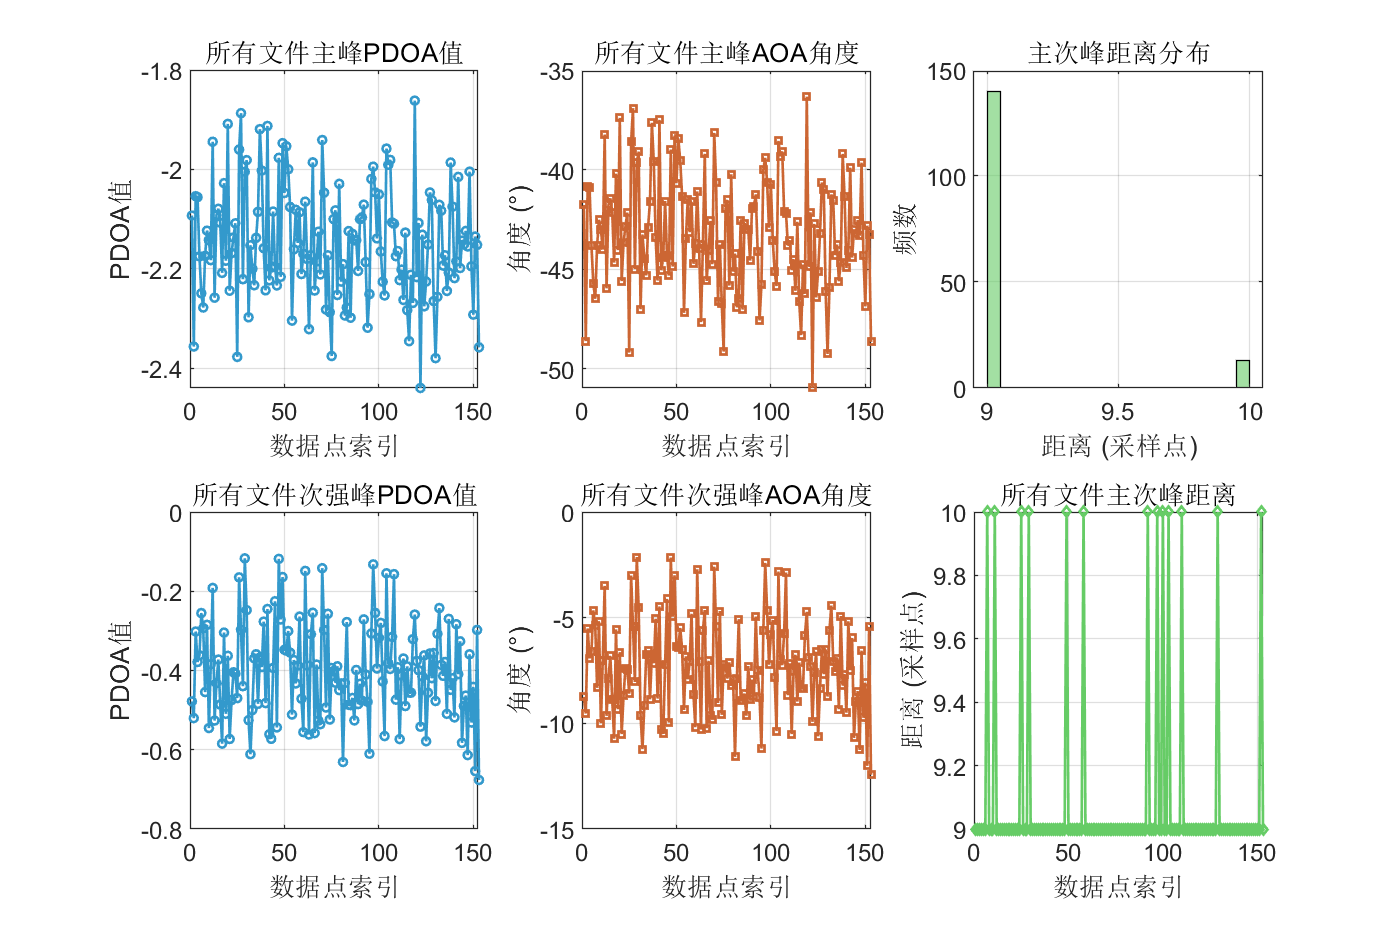

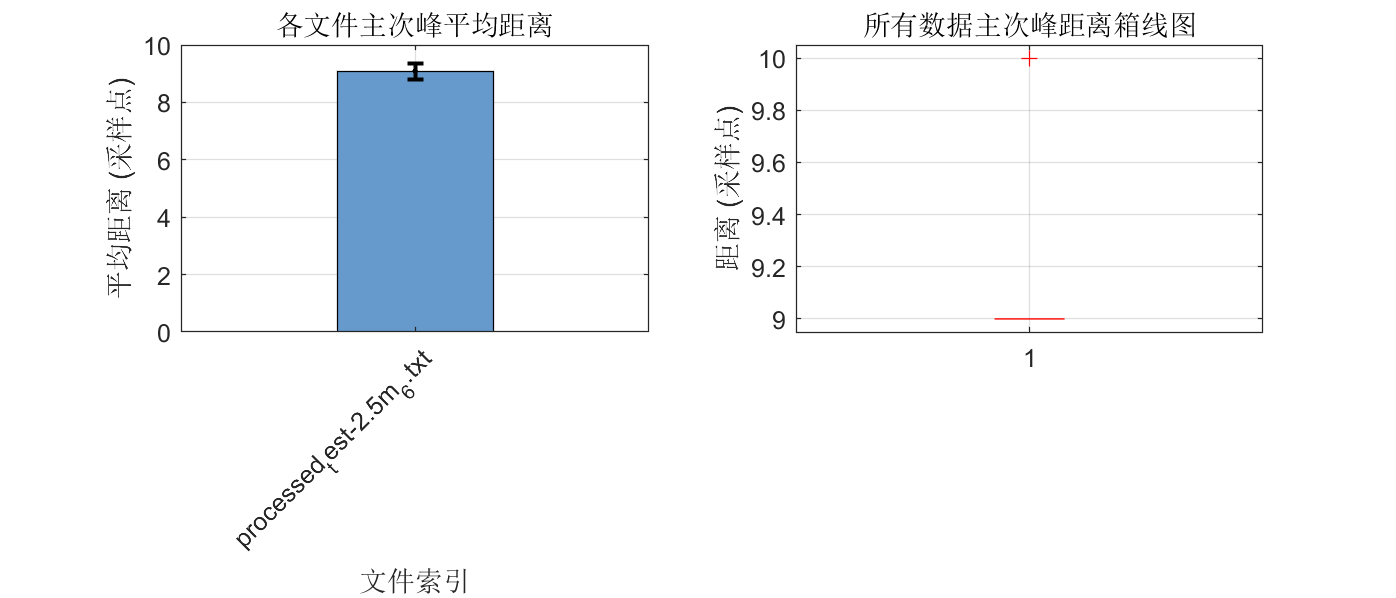

if ~isempty(all_main_pdoa)
    fprintf('主峰总体统计:\n');
    fprintf('  PDOA均值: %.4f, 标准差: %.4f\n', mean(all_main_pdoa), std(all_main_pdoa));
    fprintf('  角度均值: %.2f°, 标准差: %.2f°\n', mean(all_main_degree), std(all_main_degree));
    fprintf('  总数据点数: %d\n\n', length(all_main_pdoa));
    
    fprintf('次强峰总体统计:\n');
    fprintf('  PDOA均值: %.4f, 标准差: %.4f\n', mean(all_secondary_pdoa), std(all_secondary_pdoa));
    fprintf('  角度均值: %.2f°, 标准差: %.2f°\n', mean(all_secondary_degree), std(all_secondary_degree));
    fprintf('  总数据点数: %d\n\n', length(all_secondary_pdoa));
    
    fprintf('主次峰距离总体统计:\n');
    fprintf('  距离均值: %.2f 采样点, 标准差: %.2f\n', mean(all_peak_distances), std(all_peak_distances));
    fprintf('  最小距离: %.2f, 最大距离: %.2f\n', min(all_peak_distances), max(all_peak_distances));
    fprintf('  总数据点数: %d\n\n', length(all_peak_distances));
    
    % 绘制总体结果图
    figure('Position', [100, 100, 1200, 800]);
    
    subplot(2,3,1);
    plot(all_main_pdoa, '-o', 'LineWidth', 1, 'Color', [0.2 0.6 0.8], 'MarkerSize', 3);
    title('所有文件主峰PDOA值');
    xlabel('数据点索引');
    ylabel('PDOA值');
    grid on;
    
    subplot(2,3,2);
    plot(all_main_degree, '-s', 'LineWidth', 1, 'Color', [0.8 0.4 0.2], 'MarkerSize', 3);
    title('所有文件主峰AOA角度');
    xlabel('数据点索引');
    ylabel('角度 (°)');
    grid on;
    
    subplot(2,3,3);
    histogram(all_peak_distances, 20, 'FaceColor', [0.4 0.8 0.4]);
    title('主次峰距离分布');
    xlabel('距离 (采样点)');
    ylabel('频数');
    grid on;
    
    subplot(2,3,4);
    plot(all_secondary_pdoa, '-o', 'LineWidth', 1, 'Color', [0.2 0.6 0.8], 'MarkerSize', 3);
    title('所有文件次强峰PDOA值');
    xlabel('数据点索引');
    ylabel('PDOA值');
    grid on;
    
    subplot(2,3,5);
    plot(all_secondary_degree, '-s', 'LineWidth', 1, 'Color', [0.8 0.4 0.2], 'MarkerSize', 3);
    title('所有文件次强峰AOA角度');
    xlabel('数据点索引');
    ylabel('角度 (°)');
    grid on;
    
    subplot(2,3,6);
    plot(all_peak_distances, '-d', 'LineWidth', 1, 'Color', [0.4 0.8 0.4], 'MarkerSize', 3);
    title('所有文件主次峰距离');
    xlabel('数据点索引');
    ylabel('距离 (采样点)');
    grid on;
    
    % 绘制每个文件的结果对比图
    figure('Position', [100, 100, 1400, 600]);
    
    % 提取每个文件的平均距离
    file_names = {};
    avg_distances = [];
    std_distances = [];
    
    for i = 1:length(all_file_results)
        if ~isempty(all_file_results(i).peak_distances)
            file_names{end+1} = all_file_results(i).filename;
            avg_distances(end+1) = mean(all_file_results(i).peak_distances);
            std_distances(end+1) = std(all_file_results(i).peak_distances);
        end
    end
    
    subplot(1,2,1);
    bar(avg_distances, 'FaceColor', [0.4 0.6 0.8]);
    hold on;
    errorbar(1:length(avg_distances), avg_distances, std_distances, 'k.', 'LineWidth', 1.5);
    title('各文件主次峰平均距离');
    xlabel('文件索引');
    ylabel('平均距离 (采样点)');
    set(gca, 'XTick', 1:length(file_names), 'XTickLabel', file_names, 'XTickLabelRotation', 45);
    grid on;
    
    subplot(1,2,2);
    boxplot(all_peak_distances);
    title('所有数据主次峰距离箱线图');
    ylabel('距离 (采样点)');
    grid on;
    
else
    fprintf('没有有效数据可统计\n');
end


% 保存详细结果到文件
if ~isempty(all_file_results)
    save('peak_analysis_results.mat', 'all_file_results', 'all_main_pdoa', 'all_main_degree', ...
         'all_secondary_pdoa', 'all_secondary_degree', 'all_peak_distances');
    fprintf('\n详细结果已保存到 peak_analysis_results.mat\n');
end


详细结果已保存到 peak_analysis_results.mat
